%%% plot proportion of stuttered trials by DAF delay
clear

op.sub = 'sap006';
op.ses = 2;
op.task = 'daf'; 
op.run = 1; 
op.num_run_digits = 2; 

[dirs, host] = set_paths_ieeg_stut()

Executing (\\677-GUE-WL-0010\ROOT\CIMV2:Win32_Process.Handle="12628")->setpriority()  
Method execution successful.  
Out Parameters: 
instance of __PARAMETERS 
{ 
	ReturnValue = 0; 
}; 
 


dirs = struct with fields:
       projrepo: 'C:\docs\code\ieeg_stut'
            spm: 'C:\docs\code\spm12'
           conn: 'C:\docs\code\conn'
        FLvoice: 'C:\docs\code\FLvoice'
           data: 'C:\ieeg_stut'
           stim: 'C:\docs\code\ieeg_stut\stimuli'
         config: 'C:\docs\code\ieeg_stut\config'
    derivatives: 'C:\ieeg_stut\der'


host = '677-GUE-WL-0010'

runstring = sprintf(['%0',num2str(op.num_run_digits),'d'], op.run); % add zero padding
dirs.annot = [dirs.derivatives, filesep, 'sub-',op.sub, filesep, 'annot']; 
file_prepend = ['sub-',op.sub, '_ses-',num2str(op.ses), '_task-',op.task, '_run-',runstring,  '_']; 
beh_scoring_file = [dirs.annot, filesep, file_prepend,'beh-scoring.tsv']; 

trials = readtable(beh_scoring_file,"FileType","text",'Delimiter','tab');

ststats = grpstats(trials(:,{'delay_ms','stuttered'}),'delay_ms',{'mean'})

ststats = 4×3 table
           delay_ms    GroupCount    mean_stuttered
           ________    __________    ______________

    0          0           10             0.2      
    100      100           10             0.7      
    150      150           10             1.2      
    200      200           10             0.4      


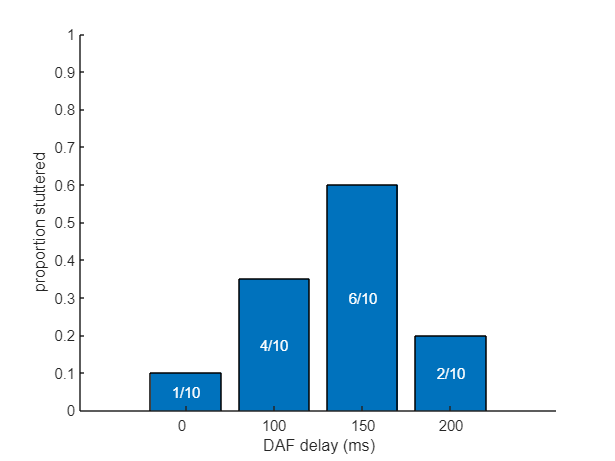


% divide 'stuttered' by 2 because 2=unambiguous, 1=ambiguous
hbar = bar(ststats.mean_stuttered / 2); hax = gca; 
box off
nconds = height(ststats);
hax.XTick = 1:nconds; 
hax.XTickLabels = ststats.delay_ms; 
ylim([0 1]); 
hylab = ylabel('proportion stuttered');
hxlab = xlabel('DAF delay (ms)');

% add text labels to bars for trial counts
for i = 1:nconds
    totaltrials = ststats.GroupCount(i);
    ntrials = round(totaltrials * ststats.mean_stuttered(i) / 2);
    label_text = sprintf('%d/%d', ntrials, totaltrials);
    
    % Position text halfway up the bar
    bar_height = ststats.mean_stuttered(i) / 2;
    text_y = bar_height / 2;
    
    text(i, text_y, label_text, 'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'middle', 'FontSize', 10, 'Color',[1 1 1]);
end